# ECE 301 HW 8 Pr 3

w = 2*pi*1000

w = 2*pi / T

T = 2*pi/w

therefore T1 = 1/1000

and T2 = 1/1100

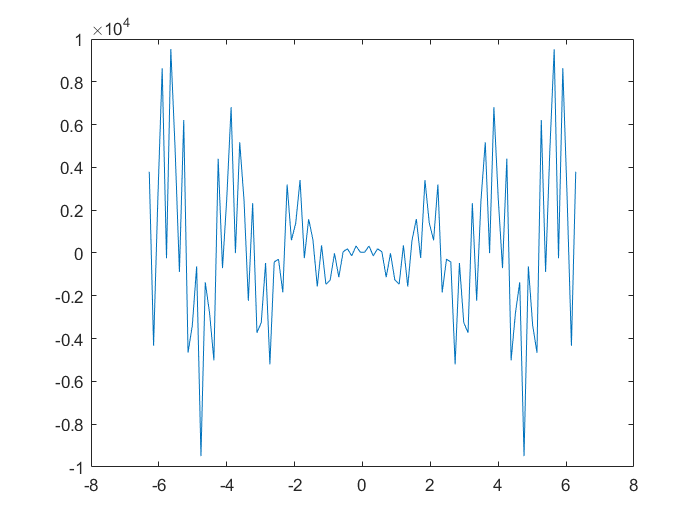

t= linspace(-2*pi,2*pi);
w1=1000;
w2=1100;
T1=1/w1;
T2=1/w2;
x=cos(2*pi*w1*t)+cos(2*pi*w2*t);
y_tria=x.*tria(t/T1);
plot(t,y_tria)

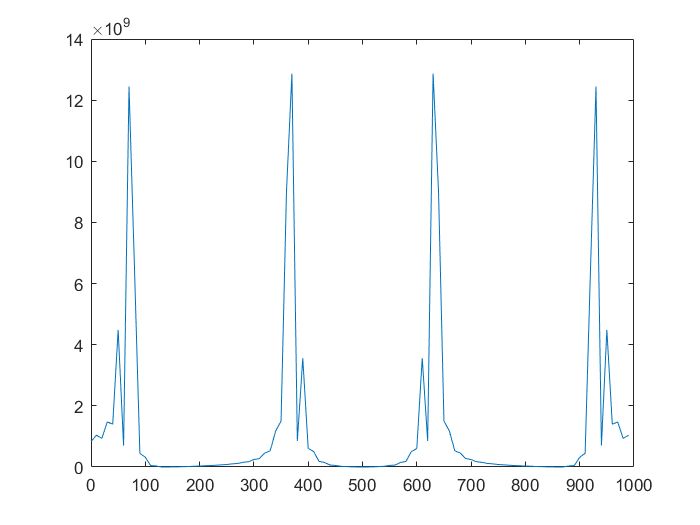

Y=fft(y_tria);
f1 = 1/T1;
f = (0:length(Y)-1)*f1/length(Y);
Y_sqd=abs(Y).^2;
plot(f,Y_sqd)

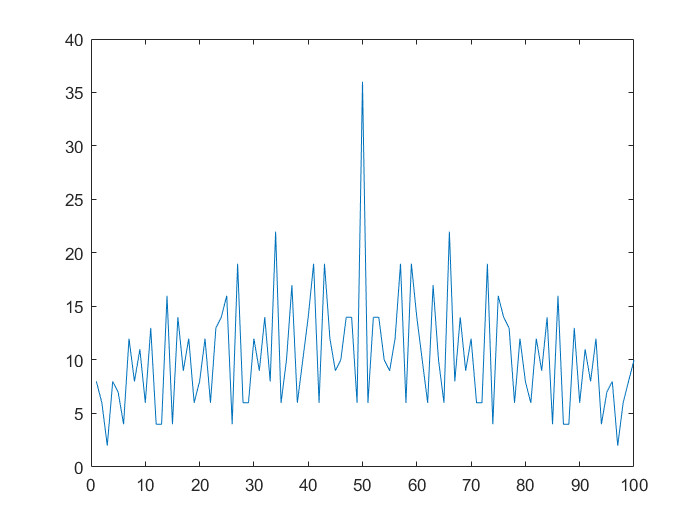

Y_FT=conv(rectangularPulse(x),rectangularPulse(x), 'same');
plot(Y_FT)